## Example #1

### 2D convex hull of random point cloud

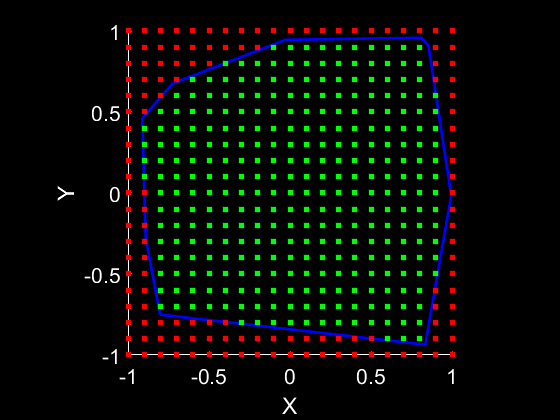

N = 28;
V = 2*(rand(N,2)-0.5);
H_raw = convhull(V);
nh = numel(H_raw);
H = repelem(H_raw',cat(2,1,2*ones(1,nh-2),1));
H = reshape(H,[2,nh-1])';
[A B] = meshgrid(-1:0.1:1);
M = cat(2,A(:),B(:));
isin = isinconvexset(V,H,M);

figure
line(V(H_raw,1),V(H_raw,2),'Color',[0 0 1],'LineWidth',2), hold on;
ColorSpec = num2cell(cat(2,~isin,isin,zeros(size(isin,1),1)),2);
cellfun(@(r1,r2) plot(r1(1,1),r1(1,2),'+','Color',r2,'MarkerSize',4,'LineWidth',4),num2cell(M,2),ColorSpec,'un',0);
set(gcf,'Color',[0 0 0]), set(gca,'Color',[0 0 0],'XColor',[1 1 1],'YColor',[1 1 1],'FontSize',16);
xlabel('X'), ylabel('Y');
axis equal, axis tight;

## Example #2

### 3D convex hull of random point cloud

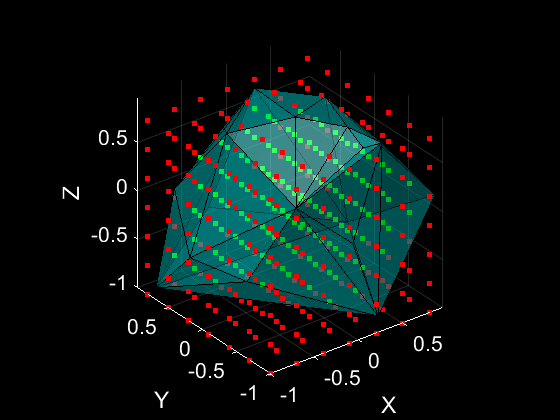

N = 32;
V = 2*(rand(N,3)-0.5);
[A B C] = meshgrid(-1:0.3:1,-1:0.3:1,-1:0.3:1);
M = cat(2,A(:),B(:),C(:));
H = convhull(V);
vtx_idx = unique(H(:));
isin = isinconvexset(V,H,M);

figure;
trisurf(H,V(:,1),V(:,2),V(:,3)), shading faceted, hold on;
colormap([0 1 1]);
ColorSpec = num2cell(cat(2,~isin,isin,zeros(size(isin,1),1)),2);
cellfun(@(r1,r2) plot3(r1(1,1),r1(1,2),r1(1,3),'+','Color',r2,'MarkerSize',4,'LineWidth',4),num2cell(M,2),ColorSpec,'un',0);
set(gcf,'Color',[0 0 0]), set(gca,'Color',[0 0 0],'XColor',[1 1 1],'YColor',[1 1 1],'ZColor',[1 1 1],'FontSize',16);
ax = gca;
ax.Clipping = 'off';
alpha(0.4);
xlabel('X'), ylabel('Y'), zlabel('Z');
axis equal, axis tight;
camlight left;